# **Exercise 31.4**

Let A be m x m upper-triangular matrix with 0.1 on the main diagonal and 1 everywhere above the diagonal.

stdsvd = zeros(1, 30);
eigsvd = zeros(1, 30);
for m = 1 : 30
    A = triu(ones(m) - eye(m) * 0.9);

Compute the smallest singular value of A:

**1) Standard SVD**

    stdsvd(m) = min(svd(A));

**2) Forming A*A and computing the square root of its smallest eigenvalue**

    eigsvd(m) = sqrt(abs(min(eig(A'*A))));

Plot the results as two curves on a log scale.

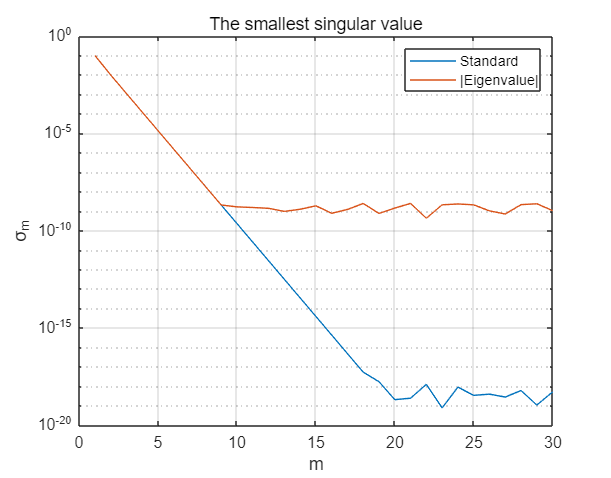

end
figure;
semilogy(1:30,stdsvd)
grid on
hold on
semilogy(1:30, eigsvd)
legend('Standard','|Eigenvalue|')
title('The smallest singular value')
xlabel('m'), ylabel('\sigma_m');